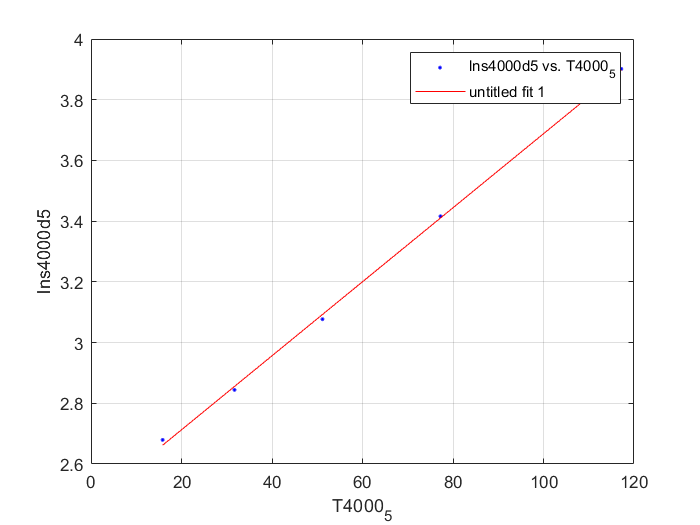

[xData, yData] = prepareCurveData( T4000_5, lns4000d5 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns4000d5 vs. T4000_5', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T4000_5
ylabel lns4000d5
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01219  (0.01157, 0.01281)
  %     p2 =       2.469  (2.426, 2.512)

%Goodness of fit:
 % SSE: 0.0007321
  %R-square: 0.9992
  %Adjusted R-square: 0.999
 % RMSE: 0.01562